# Persephone Tutorial 1: Creation of the conifguration file

Authors: Bram Nap

Last updated: April 2026

The Persephone pipeline can be executed using just one command - ‘runPersephone’. The input for that command is a configuration file that contains the paths to the relevant data and the user preferences for each step of the analysis. Once you have composed a configuration file, all the hard work is done. The configuration file can be created and downloaded from: [https://delta.vmh.life/persephone](https://delta.vmh.life/persephone) 

Under the *Toolbox*drop-down menu on the landing page, select ‘Persephone’, and that will take you to a page with the configuration. Here you will see eight drop-down tabs. The first contains useful links and information that will help you with your setup. It is important to read through this as there is some critical information, essential software and download files here that you will need for running some sections of Persephone. For a full example of Persephone outputs, please refer to the demo datasets.

## How to: Essential installations

To use Persephone, you need to install:

- MATLAB. A 30-day trial license is available if you do not have a MATLAB license through your institution. To download and install MATLAB, please refer to the official MathWorks website. [https://uk.mathworks.com/products/matlab.html](https://uk.mathworks.com/products/matlab.html)

- It is important that during installation you also install the parallel computing toolbox, which is required for various functions in Persephone and the statistics and machine learning toolbox, which is required for the statistics part of Persephone.

- The COBRA toolbox. The codebase of Persephone is in the COBRA toolbox and is therefore required to be downloaded and installed. To download and install the COBRA toolbox, please refer to the installation instructions: [https://opencobra.github.io/cobratoolbox/stable/installation.html](https://opencobra.github.io/cobratoolbox/stable/installation.html)

- A solver for linear/quadratic programming. Persephone performs linear optimisation and requires a third party solver to ensure computation happens in a timely manner. For installing solvers and solver compatibility with MATLAB and the COBRA toolbox, please see: [https://opencobra.github.io/cobratoolbox/stable/installation.html#](https://opencobra.github.io/cobratoolbox/stable/installation.html)

- If you run SeqC, please install Docker. Persephone communicates with Docker to run SeqC. To install Docker, please see the official site [https://www.docker.com](https://www.docker.com)

- If working on an HPC, you will need to install Apptainer to run Docker. For the installation instructions, see  [https://apptainer.org/get-started/](https://apptainer.org/get-started/). For help running MATLAB on HPC, see [https://uk.mathworks.com/help/ matlab-parallel-server/configure-parallel-computing-products-for-hpc-server.html](https://uk.mathworks.com/help/%20matlab-parallel-server/configure-parallel-computing-products-for-hpc-server.html)

## How to: Preparing your input data

It is good practice to have all the input files required for a Persephone run in a single directory. Create a single directory/folder that you can easily find and access, called e.g., inputsPersephone. In the directory for Persephone inputs, store the following files:

- The metadata file. This file has to have a column with a header called ID that contains the sample IDs and a column with a header called Sex. The sex column needs to have female/male or F/M as values. Other columns can be present in the metadata and used for personalisation or statistics. For metadata headers used in personalisation, please refer to Persephone tutorial 2 or the main text of the Persephone paper, protocol Phase 2.

- If community microbiome models have to be created, there are three starting points in Persephone requiring different input data.                                                     **A)** Raw .fastq files. This requires SeqC to be enabled. Please store the .fastq files in the cobratoolbox location cobratoolbox/src/analysis/Persephone/SeqC_pipeline/seqc_input/. In the same location. also store the sample ID file. The sample ID file should contain the IDs of the samples used and should correspond to the filenames of the .fastq files.                                                                                                                                         **B)** If you have already processed the raw .fastq files, you can use the taxonomy-assigned reads table. It should have a column called Taxon containing the taxonomies. If it has taxonomic units such as OTUs or ASVs, please also store a file that translates the taxonomic unit to the taxonomic assignment. The taxonomic assignment in the translation table should be called Taxon, and the taxonomic unit column in both tables should have the same name. Ensure that in the taxonomic reads table, the sample names are the same as in the metadata. To use the taxonomy-assigned reads table, please enable MARS.                         **C)** If you already have relative abundance data that is mapped to a reconstruction database, you can skip SeqC and MARS and only enable MgPipe. Ensure that the reconstruction names in the relative abundance file match the file names of the reconstructions and that the sample names match the metadata.

- If community microbiome models are created, a directory with the microbe reconstructions is required. For the AGORA2 and APOLLO pan-species models, please refer to the Materials section of the Persephone paper.

## How to: Find a path on your local device

If you want to use a file explorer or the desktop terminal/command prompt, please refer to the official explanation on how to obtain file paths from your operating system of choice.

Using MATLAB (Figure 1):

In red box 1, you will find the path to the directory you are currently in. The contents of the directory are shown in red box 2. You can navigate through the computer directories by double-clicking on folders in box 2 or by clicking the required directory in the address bar (box 1). Once you have navigated to your desired directory, click the address bar (box 1) in an area without text to select the full path to your current directory. You can copy and paste that text into the online configuration maker. If a file location is required, you should also give the filename AND extensions. To do so, add an / or \ to the end of the directory path you just copied. The type of slash depends on your system and should match the other slashes used in the directory path. Add in the full file name and extension after the slash. For ease, click on the required file once in box 2, select everything and copy the text. You can then paste this into the directory path to obtain the full file path.

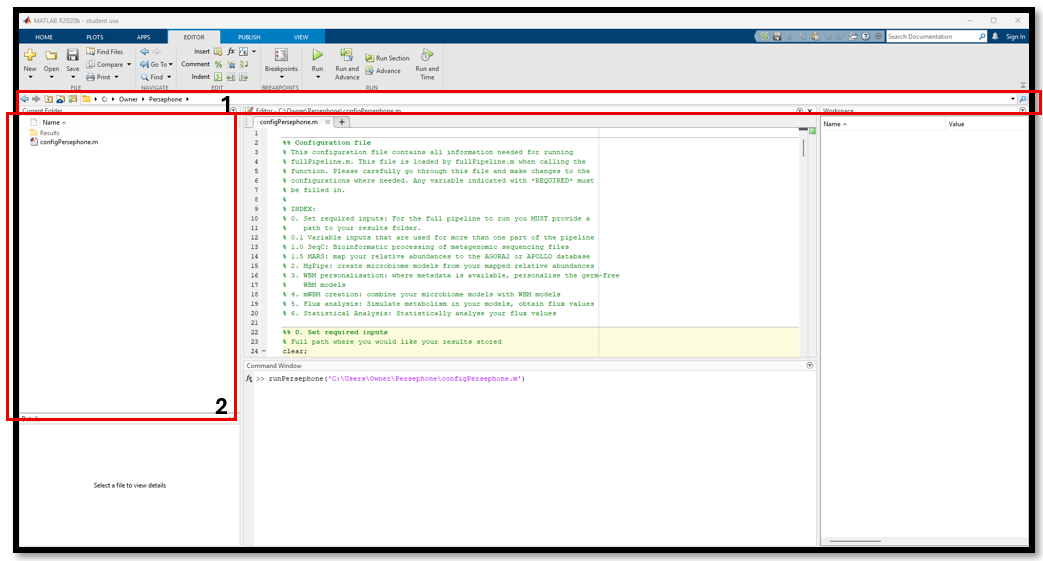

*Figure **1**. *Screenshot of the MATLAB user interface. Red box one shows the address bar and shows in which directory MATLAB is in. Red box 2 shows the files and directories available in the current directory MATLAB is in.

## How to: Create the configuration file

The four phases outline the different operations performed in Persephone. Each phase has a corresponding tutorial that goes into detail on how the code works and gives additional insights into metabolic modelling. In this tutorial, the different inputs for each phase are discussed, including what to fill in and how it may affect the data. The variable names in blue and bold are the variable names as found in the online configuration file creator. In brackets after the bold variable name is the variable name as used in the runPersephone code, if you want to alter the variables directly in the configuration file once downloaded. The data type used in MATLAB is also given, to help you fill in the correct format if you want to alter the configuration file itself. It is worth spending some time carefully filling out each section. After you have completed each section, you simply hit the download button, and then you have the only input that you need to execute ‘runPersephone’ in MATLAB.

## Set global inputs

Before you fill in the inputs for the specific phases of Persephone, there are some global variables that need to be defined. These global variables are used in different steps within Persephone and are therefore defined at the start (Figure 2). 

- Persephone needs to know where all the produced results should be saved on your device. In the **Result Path** (resultsPath) variable, you can set the path where you want Persephone to store the results. As Persephone creates all the output storage locations, you do not need to define them yourself. It is highly recommended that you do not change the default output paths for the other steps in Persephone. When editing the configuration file in MATLAB, ensure that an apostrophe (‘) is at the start and end of the path to make sure MATLAB reads it as text.

- Metadata is also required to run Persephone. It needs to know which samples should be linked to which sex-specific WBM. Additionally, if you want to perform personalisation and statistics, the same information is required to be included in the metadata file. If you only want to create community microbiome models, add a column with fake female/male data to ensure Persephone runs. The location of the metadata file can be specified in the **Metadata Path** (metadataPath) variable. To reiterate, the minimum required content of the metadata file is a column with the header ID and a column with the header Sex. When editing the configuration file in MATLAB, ensure that an apostrophe (‘) is at the start and end of the path so MATLAB reads it as text.

- The diet determines which metabolites the WBMs can use. This is important because enough metabolites must be available for the whole-body maintenance reaction and, if applicable, to support the growth of the gut microbiome. The default diet is the European average diet (EUAverageDiet), but the COBRA toolbox includes many alternative diets. The diet can be defined either as a diet name in the COBRA toolbox or as a path to a diet file on your local device and set as the **Diet** (diet) input variable. Alternatively, after downloading the configuration file, the diet can be set as an *nx2* cell array. For first-time users, it is recommended to use the default EUAverageDiet. When editing the configuration file in MATLAB, ensure that an apostrophe (‘) is at the start and end of the diet name or diet file path to make sure MATLAB reads it as text. Alternatively, use {} to indicate a cell array, with commas and line breaks to structure the array.

- The computations performed by Persephone require the use of an industrial solver,  not the standard MATLAB solver, glpk. Various industrial solvers can be used: Mosek, IBM CPLEX, TOMLAB, and Gurobi. In the drop-down menu for the input variable **Solver**(solver), you can choose which solver is installed on your machine and you want to use. We recommend using Gurobi, as the installation procedures are straightforward and an academic license is easily obtainable. When editing the configuration file in MATLAB, ensure that an apostrophe (‘) is at the start and end of the path to make sure MATLAB reads it as text.

- Persephone makes use of parallelisation and requires the user to specify the number of parallel instances MATLAB can use to perform processes.  There are two different operations that are parallelised in Persephone: model creation and model optimisation. They are split because they require different approaches in setting the number of workers (parallel instances used by MATLAB). The number of workers **(Number of workers creation) **(numWorkersCreation) can be a high number of workers, as more workers are used, which means less time is spent in total performing the work. We advise using 80% of the total number of workers available on your machine, if you want to use the machine for other purposes besides running Persephone. To find the total number of workers available on your machine, run >>feature(‘numcores’) in the MATLAB terminal window. When editing the configuration file in MATLAB, use only numbers (no decimals). No apostrophes are required.

- For the number of workers for **Number of Workers (optimisation) **(numWorkersOptimisation), we recommend using only 1 worker. Industrial solvers typically already parallelise their optimisation, which means that using more workers in MATLAB to optimise multiple reactions at once will increase the total computation time. On stronger desktops, this number can be increased. When editing the configuration file in MATLAB, use only numbers, no decimals. No apostrophes are required.

% To find the total number of cores on you computer
cores = feature('numcores');
cores

cores = 18

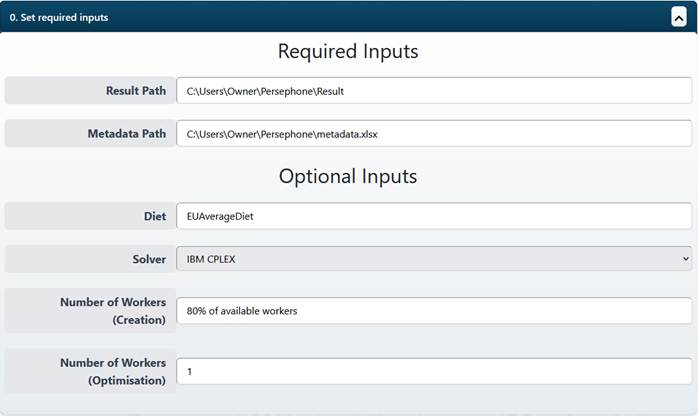

*Figure **2**. Various inputs that are used in multiple steps in Persephone. Of these only the directory to the result storage and the location of the metadata are required.*

## Phase 1 inputs: Creation of community microbiome models

### SeqC inputs

SeqC is a bioinformatics pipeline for processing sequencing data to generate taxonomic profiles that seamlessly integrate with the rest of Persephone. Should you wish to use  SeqC, the following guidance is relevant (Figure 3): 

- From the configuration menu, set **Enable SeqC Processing** (flagSeqC) to True. In addition to enabling SeqC, this will reveal other relevant input fields. When editing the configuration file in MATLAB, only use true or false as the input, without quotation marks or apostrophes.

- **SeqC Repository Path** (repoPathSeqC) defines the system path to the folder *SeqC_pipeline,* which is located in cobratoolbox\src\analysis\persephone. Once you have cloned the cobratoolbox, you will just need to adjust the first part of this path. When editing the configuration file in MATLAB, ensure that an apostrophe (‘) is at the start and end of the path to make sure MATLAB reads it as text.

- Next, you will need to create a text file listing the unique identifiers of the sequencing files (e.g., sample1 for sample1_R1.fastq and sample1_R2.fastq). Store this file within the *seqc_input*sub-folder inside the *SeqC_pipeline* folder. Enter the filename (not path) of the file into the **Sample ID File **(fileIDSeqC) variable. When editing the configuration file in MATLAB, ensure that an apostrophe (‘) is at the start and end of the file name to make sure MATLAB reads it as text.

- **SeqC Output Path** (outputPathSeqC), which defines the relative location where outputs for this step are written, can be adjusted. By default, the results are written to a subdirectory called ResultSeqC—located in the previously defined results folder. If you want to edit this path in the configuration file in MATLAB, ensure that an apostrophe (‘) is at the start and end of the path to make sure MATLAB reads it as text.

- By default, the intermediary outputs will be deleted to save space, but this feature can be disabled by setting **Retain Intermediary Outputs** (procKeepSeqC) to True. When editing the configuration file in MATLAB, only use true or false as input, without apostrophes.

- **Max Memory (GB)** (maxMemSeqC) refers to the amount of memory (RAM) in GB that can be used while executing SeqC. As outlined in the accompanying manuscript, this section of Persephone is designed to be run on a powerful computer. The default, set at 20 GB to reflect average laptop hardware, is suitable for running the demo set (just 4 models). However, if you want to run a large number of samples, we recommend using a more powerful setup and increasing this input. When editing the configuration file in MATLAB, use only numbers (no decimals). No apostrophes are required.

- 80% of the total available CPUs is the default set for **Max CPU Threads** (maxCpuSeqC). [[BN1]](about:blank<#_msocom_1%3E) This will automatically adjust based on the computer you are using to ensure the process is optimised without totally compromising other functions of your device. **Max Processes**(maxProcSeqC) has a default value of 1, and corresponds to the number of processing instances used by *some* pipeline components. It can be adjusted in conjunction with **Max CPU Threads** to further manage resources. The product of the two variables should not exceed the total number of CPU threads on the system. Alternatively, you can adjust these parameters to your own preferences. When editing the configuration file in MATLAB, use only numbers, no decimals. No apostrophes are required.

- For a more verbose record of the SeqC run, which can aid in troubleshooting and better understanding of the bioinformatic process, set **Enable Debug Logging** (debugSeqC) to True and additional content will be added to the internal log file (found in the ResultsSeqC directory). When editing the configuration file in MATLAB, only use true or false as input, no apostrophes.

- If you are running SeqC on a computer system with restrictive user permissions or a job scheduler (e.g., SLURM), and *Apptainer* (formerly Singularity) is installed, setting **Run Apptainer** (runApptainer) to True will use Apptainer to build and run the SeqC container instead of Docker. When editing the configuration file in MATLAB, only use true or false as input, no apostrophes.

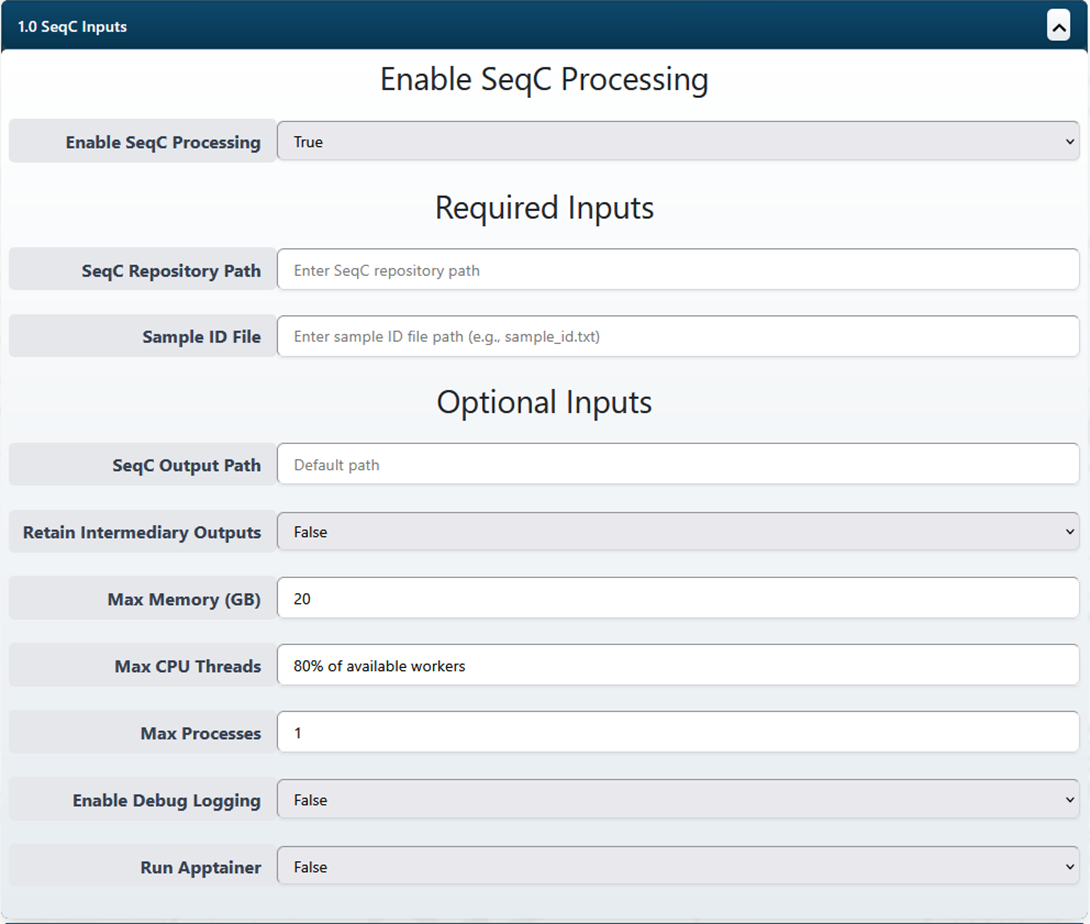

*Figure **3**. Various input parameters to run SeqC. To see and fill in the input variables, set Enable SeqC Processing to true. The SeqC Repository path and the name of the Sample ID file are the only required variables. *

Following a successful run, products of the pipeline will be located within the ResultSeqC folder. At a minimum, you will find the following files: 

- The taxonomic profile with values in relative abundance (KB_S_mpa_out_RA.txt) and read counts (KB_S_mpa_out_RC.txt). The naming convention is Kraken/Bracken (KB), species (S), Metagenomic Phylogenetic Analysis (MPA), and either relative abundance or read count. The read count table is what serves as input for the next step of Persephone.

- A log file with the following name structure: log_seqc_project_YYYYMMDD.txt. This file contains information about the processing of your samples and references for the tools that were used.

### MARS inputs

To convert taxonomy-assigned reads, obtained from SeqC or from a third-party software like QIITA, into input that can be used to create community microbiome models requires various steps and conversions, all of which are performed in MARS. Here, we will go over the various inputs for MARS that are used in Persephone. This section will guide you step by step on how to set the various input variables and how they affect the results. Be aware that some options will be locked to their default values if SeqC is enabled to ensure proper data handling (Figure 4).

- To enable Persephone to run MARS, you need to set **Enable MARS Processing** (flagMars) to True. In the online configuration file maker, this will allow you to fill in the rest of the input variables. When editing the configuration file in MATLAB, only use true or false as input, without apostrophes.

- The only required variable you need to define is the **Reads Table Path **(readsTablePath) variable. This is the location of the reads table on your local device. If you run SeqC, it is locked to its default value. When editing the configuration file in MATLAB, ensure that an apostrophe (‘) is at the start and end of the path to make sure MATLAB reads it as text.

We will now go over some input variables that concern the taxonomic assignment.

- Open the reads table in your editor of choice. Double-check if the first column header (cell A1 if opened in Excel) is called “Taxon” and contains the taxonomic assignments. If it does, you can exit the document and leave **Taxa Table Path **(taxaTablePath) empty, or in MATLAB as an empty string, i.e., “”. If your reads table does not contain a column with taxonomic assignment, but instead contains a column called ‘OTU’ or ‘ASV’, or another way of indicating taxonomic grouping, you will need a second table to translate those taxonomic groupings into taxonomic assignments, which can be filled in the **Taxa Table Path **variable. The variable takes the path to the file containing the link between the taxonomic grouping and the taxonomic assignment. It is important that the column in taxonomy table with the taxonomic assignment is called ‘Taxon’ and that the columns with taxonomic grouping in the reads table and taxonomy table share the same column header. If they do not, the reads table and taxonomy table cannot be linked, and the taxonomy assignment cannot be transferred. Please ensure that the taxonomy grouping column in the reads table is the first column. When editing the configuration file in MATLAB, ensure that an apostrophe (‘) is at the start and end of the path to make sure MATLAB reads it as text.

- Look at the taxonomic assignments either in the reads table or the taxa table. The different taxonomic levels should be separated by a delimiter, which should be filled in **Taxa Delimiter** (taxaDelimiter) input variable. E.g., “Archaea; Euryarchaeota; Methanobacteria; Methanobacteriales; Methanobacteriaceae; Methanobrevibacter; smithii” the delimiter is “;” and for “k__Bacteria|p__Bacteroidetes| c__Bacteroidia|o__Bacteroidales|f__Rikenellaceae|g__Alistipes|s__Alistipes_putredinis” the delimiter is “|”. Quotation marks are not required when using the online configuration file creator. If you do not choose the right delimiter, the split of taxonomic levels in MARS will not be performed properly, and Persephone will give you an error. This variable is locked when SeqC is run. When editing the configuration file in MATLAB, ensure that an apostrophe (‘) is at the start and end of the delimiter to make sure MATLAB reads it as text.

- In the AGORA2 and APOLLO databases, the species are named by the following convention: genus name species name, e.g., *Egerthella lenta*. That means we have to search for genus+species name combinations in the database. The **Lone Species Flag** (loneSpeciesFlag) is a true /false input statement that says whether or not the genus name is already in the species name in your input data. E.g., “Archaea; Euryarchaeota; Methanobacteria; Methanobacteriales; Methanobacteriaceae; Methanobrevibacter; smithii” the genus name is Methanobrevibacter, and the species name is smithii. This means the species name does not carry the genus name, and would set **Lone Species Flag** (loneSpeciesFlag) to true. For “k__Bacteria|p__Bacteroidetes|c__Bacteroidia|o__Bacteroidales|f__Rikenellaceae|g__Alistipes|s__Alistipes_putredinis” the genus name is Alistipes and the species name is Alistipes putredinis. This means the genus name is in the species name and you would set **Lone Species Flag** (loneSpeciesFlag) to false. MARS will automatically add the genus name to the species if the **Lone Species Flag** (loneSpeciesFlag) variable is set to true. A mistake here could mean the genus name is not added, and only smithii is searched, or it could mean that the genus name is added again, and it searches for Alistipes Alistipes putredinis in the databases. If you use a different database, other than AGORA2 or APOLLO, check if the column for species names includes the genus name or not, and adjust the input accordingly. This variable is locked when SeqC is run. When editing the configuration file in MATLAB, only use true or false as input, without apostrophes.

- Depending on how the taxonomies were assigned, they might include clades, e.g., *Eggerthella lenta A*. As AGORA2 and APOLLO do not account for clades, these specific naming instances will not be matched with the database. Therefore, MARS has the option to remove the clade names to increase the number of reads mapped onto the databases. If you want clade names to be removed, set to **Remove Clade Names** (removeCladeNames) true. If you want to keep clade names, set **Remove Clade Names** (removeClade) to false: note that you might lose reads, as they could not be mapped. When editing the configuration file in MATLAB, only use true or false as input, without apostrophes.

- It is important to know how your taxonomic reads table is structured in terms of read handling. Usually, your read data is compounded or it is not. It is important to know this, as MARS will treat your data differently. Compounded data is specified in the input variable **Compounded Database**(compoundedReads), where true mean the reads are compounded. Compounded reads mean that the read counts for higher taxonomic ranks (e.g., Phylum) are based on those of lower subordinate rank. Choosing the wrong option, true/false will not have an effect on the mapped relative abundance of species. However, higher taxonomic levels will get skewed or incorrect results if the wrong option is used, as well as the Firmicutes / Bacteroidetes ratio. 

The last few input variables concern different ways the data is handled and how the output for community microbiome model creation is produced.

- Generally, the total reads of a sample are far greater than 100.000. If there is a sample that, for example only has 100 reads, it could be an indication that something went wrong during sequencing or processing of the data. The input variable **Sample Read Counts Cutoff **(sampleReadCountCutoff) is used to specify the cutoff where samples with a total read count below that set cutoff are removed from the relative abundance table. The default value is one. If you work with already normalised data, you might want to change the value to less than 1, to ensure no samples were removed, as typically normalised data adds up to one. When editing the configuration file in MATLAB, use only numbers. No apostrophes are required.

- During the processing of the read data, MARS normalises every sample to 1 and checks if any of the taxonomic assignments’ normalised values are beneath the variable **Cutoff MARS** (cutoffMars). The default value is 1e-6 to prevent numerical difficulties/infeasibilities during later steps. It is not recommended to lower this value; increasing the value should be done with caution, as you can remove taxa. MARS will output a table with the taxa removed due to the cutoff for each sample. When editing the configuration file in MATLAB, use only numbers. No apostrophes are required.

- The place where the MARS results are stored is defined in the variable **Output Path MARS **(outputPathMars). The variable is prefilled as Persephone is designed to have results in an easily accessible directory and is thus not recommended to change this variable. If you want to edit this path in the configuration file in MATLAB, ensure that an apostrophe (‘) is at the start and end of the path to make sure MATLAB reads it as text.

- There are four types of microbiome pan-species databases you can choose from in Persephone. The choice of database is made in the **Reconstruction Database** (databaseType) variable. It has a drop-down menu where you can choose from APOLLO (just APOLLO), AGORA2 (just AGORA2), full_db (both AGORA2 and APOLLO)  and user_db (user-defined database). If you want to use your own pan-species database, be that an older version of AGORA2 or APOLLO or a different database, set the location of that database on your local machine with the **User Database path** (databasePath) variable. The database file should be in .csv, .txt, .parquet or .xlsx format and have taxonomic levels as column names. Note that the user database needs to have the same structure as the integrated AGORA2 & APOLLO database to function properly. If you want to edit this path in the configuration file in MATLAB, ensure that an apostrophe (‘) is at the start and end of the path to make sure MATLAB reads it as text.

- MARS has the option to calculate the Bray-Curtis dissimilarity index. To enable the calculation, set the input variable **Calculate Bray Curtis Dissimilarity** (calculateBrayCurtis) to true. If you have over 100 samples, calculating Bray-Curtis is not recommended unless it is essential for analysis, as the calculations become time-consuming.

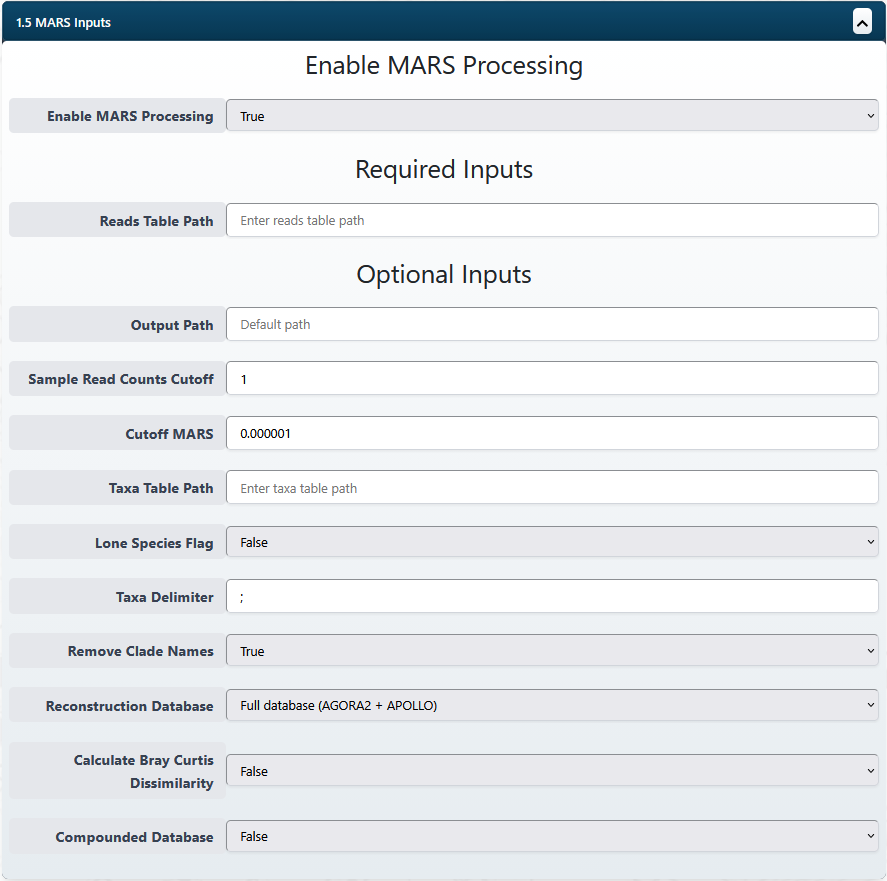

*Figure 4. Various input parameters to run MARS. To see and fill in the input variables, set Enable MARS Processing to true. The reads table path is the only required input, if SeqC is false. If SeqC is true, the reads table path will be locked*

Following a successful run, products of the pipeline will be located within the ResultMars folder. You will find the following directories:

- Mapped – Here is where, for each taxonomic level, non-normalised reads are stored that could be mapped to the reconstruction database. Its main use is for calculating various metrics and figure creation.

- Mapped_forModelling – Here is where the normalised reads, better known as relative abundances, for the mapped taxonomic levels are stored. The species file is used by MgPipe to create community microbiome models.

- Metrics – For each taxonomic level, various metrics and summary statistics are stored and can be used to assess the quality of mapping.

- Processed – For each taxonomic level, the non-normalised reads are stored after they have gone through processing in MARS. This is to show what reads are available for that specific taxonomic level and how processing affects the data.

- Unmapped – The reverse of the mapped folder. Here, for each taxonomic level, are the associated reads for the taxa that could not be mapped to a reconstruction database. This can be used as a sanity check to see if any taxa that should be mapped aren’t mapped.

### MgPipe inputs

MgPipe constructs and tests community microbiome models. It requires the output from MARS or a user-created relative abundance file. Here we will explain the input variables used by Persephone to run MgPipe. If MARS is enabled in the online configuration file, some fields will be locked to their default settings to ensure correct data handling (Figure 5).

- To allow Persephone to run MgPipe, you need to set the **Enable MgPipe**(flagMgPipe) variable to True. In the online configuration file maker, this will also allow you to fill in the rest of the input variables. When editing the configuration file in MATLAB, only use true or false as input, without apostrophes.

- The **Relative abundance file path **(relAbundPath) input variable is required, as it indicates which microbial models are used in each sample, with their respective contribution to the microbiome in the form of relative abundance. If MARS is run in Persephone, you do not have to adjust this input variable, as it will automatically point to the correct output directory of MARS. If MARS was not run in Persephone and the relative abundance file was created in a prior run or through other means, you will have to change the value of the **Relative abundance file path **(relAbundPath) variable to the path pointing to your relative abundance file path, and remember to add the file extension! It is important that the relative abundance of all samples must add up to 1. If there are samples that have a total relative abundance of 0, they can cause issues in MgPipe. MARS has the ability to remove these samples if enabled. When editing the configuration file in MATLAB, ensure that an apostrophe (‘) is at the start and end of the path to make sure MATLAB reads it as text. 

- In the **Microbe Reconstruction Path **(microbeReconstructionPath) variable, put in the path to the directory on your device where you have stored the microbial reconstructions. The link to AGORA2 and APOLLO models can be found at the start of the online configuration portal or in the Persephone Nature Protocol paper. It is important that the names of the models in the relative abundance file match the filenames of the actual microbial reconstructions. When editing the configuration file in MATLAB, ensure that an apostrophe (‘) is at the start and end of the path to make sure MATLAB reads it as text.

- The place where the MgPipe results are stored is defined in the variable **Output Path MgPipe** (outputPathMgPipe). The variable is prefilled, as Persephone is designed to have results in an easily accessible directory and is thus not recommended to change this variable. When editing the configuration file in MATLAB, ensure that an apostrophe (‘) is at the start and end of the path to make sure MATLAB reads it as text.

- MgPipe is capable of calculating the metabolite production and consumption profile of the created community microbiome models.  To perform that calculation, set **Compute Profiles **(computeProfiles) to True. It is important to know that this can take some time to compute and will increase the total run time of Persephone. When editing the configuration file in MATLAB, only use true or false as input, without apostrophes.

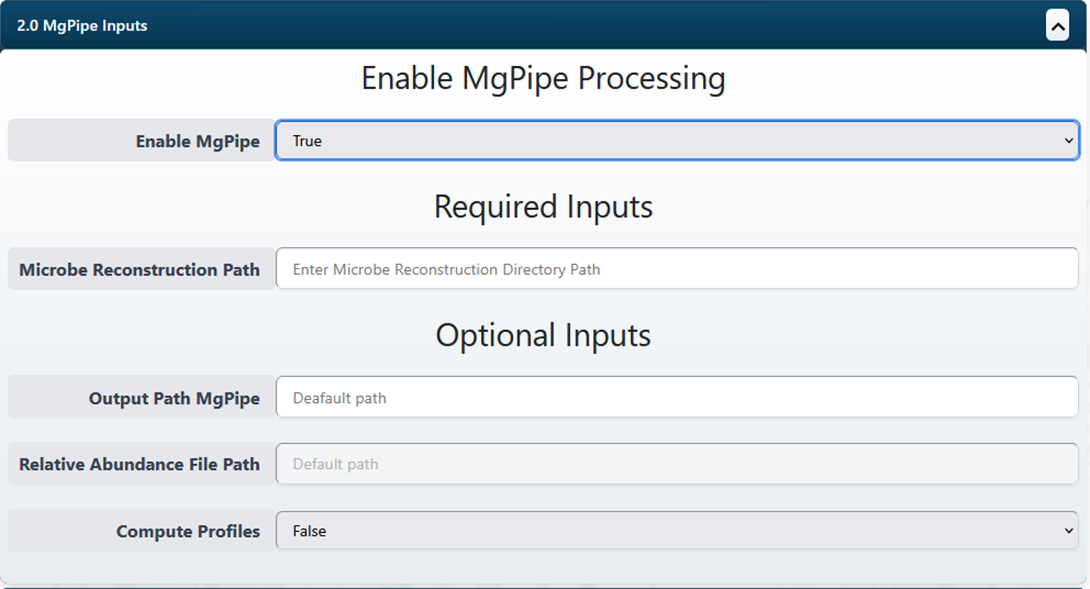

*Figure **5**. Various input parameters to run MgPipe. To see and fill in the input variables, set Enable MgPipe to true. The only required variable is the microbe reconstruction path. The relative abundance file path will be locked if MARS is set to true. Otherwise this is a required input.*

Following a successful run, products of the pipeline will be located within the resultMgPipe folder. You will find the results:

- Folder called Diet. Here, diet-constrained community microbiome models are stored.

- Folder called modelStorage. Here, the adjusted individual pan-species models are stored.

- The unconstrained community microbiome models. They can be recognised as they have microbiome_model_samp at the start of the file name.

- Various files describing reaction abundance and presence, subsystem abundance, a heatmap, and summary statistics

- If computeProfiles is True, files showing the net uptake and excretion rates are stored, as well as a principal component analysis plot of the flux results.

## Phase 2: WBM Personalisation inputs

WBM personalisation uses metadata, specifically physiological and metabolomics data, to adapt the constraints on the WBM so that they reflect the provided readings (Figure 6).

- To personalise your WBMs when running Persephone, first set **Enable WBM Personalisation** (flagPersonalise) to True. In the online configuration file maker, this will also allow you to fill in the rest of the input variables. When editing the configuration file in MATLAB, only use true or false as input, without apostrophes.

- Next, set the **Output Path for Personalisation**(outputPathPersonalisation). This defines where the personalised WBMs and the function’s output files (including a summary of personalised parameters) will be stored. By default, this path follows the pre-defined structure, which we recommend keeping, especially if you are running multiple steps of Persephone. If you want to edit this path in the configuration file in MATLAB, ensure that an apostrophe (‘) is at the start and end of the path to make sure MATLAB reads it as text.

- **Physiological Parameters** (persPhysiology): list the physiological parameters you wish to personalise. For a full list of physiological parameters you can personalise, refer to the Persephone paper. Separate multiple entries with commas. Ensure the values entered have a corresponding header in your metadata file. When editing the configuration file in MATLAB, ensure this value starts with { and ends with }. Each value inside the two curly brackets must be separated by a comma and be between apostrophes so MATLAB recognises it as text. E.g., {‘Weight’, ‘Cardiac Output’}.

- **Metabolomic Parameters** (persMetabolites): list the metabolites to be used for constraining the model. Each metabolite must be given as a VMH ID (search at [https://vmh.life/](https://vmh.life/)) and include the biofluid compartment where the measurement was taken. Currently supported compartments are *blood [bc], urine [u],* and *cerebrospinal fluid [csf]*. Use a comma to separate the metabolite from its compartment, and a semicolon to separate different metabolite–compartment pairs. Ensure the values entered have a corresponding header in your metadata file. When editing the configuration file in MATLAB, ensure this value starts with { and ends with }. Each pair inside the two curly brackets has to be separated by a comma, and each new metabolite with an enter or semicolon “;”. Metabolite names need to be in-between apostrophes, so MATLAB recognises it as text. E.g. {MetaboliteID, Compartment; NextMetaboliteID, Compartment}.

- If you do not want to use the default WBMs (Harvetta and Harvey) for personalisation, you can give the file path location to your own female and male WBMs. These can differ from the default WBMs by, for example, accounting for gene silencing or having added reactions based on your own project. Use **Path to User Defined female WBM **(femaleWBMPath) and **Path to User Defined Male WBM** (maleWBMPath) to specify the file path for the alternative female and male WBMs to be used, respectively. When editing the configuration file in MATLAB, ensure that an apostrophe (‘) is at the start and end of the path to make sure MATLAB reads it as text.

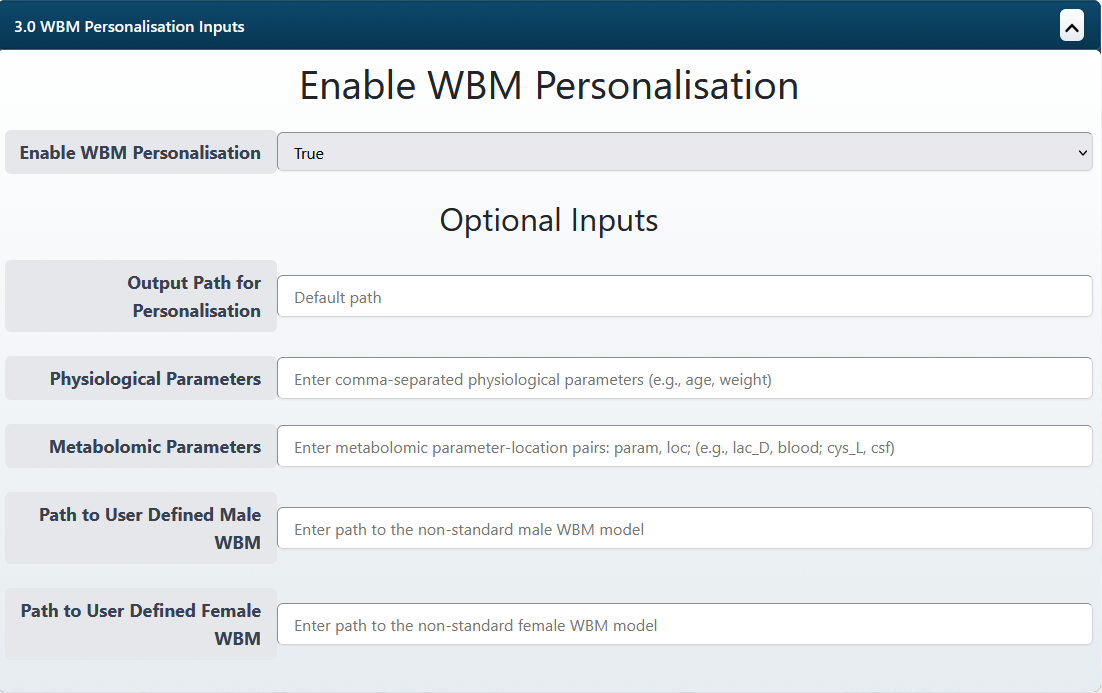

*Figure **6**. Various input parameters to personalise the WBM. To see and fill in the input variables, set Enable WBM Personalisation to true. No required variables, but if no physiological or metabolomic parameters are given, no personalisation is performed.*

Following a successful run, products of the pipeline will be located within the personalisedWBMs folder. You will find the results:

- Personalised WBMs. They can be identified by their file name as they contain iWBM and the sample ID.

- A file containing feasibility checks on the personalised WBMs. This can be used to find out which WBMs were infeasible and could not be fixed by updating the diet.

- A file containing conflicting bounds on the WBMs as a cause of the personalisation (where relevant). The reactions causing the conflicts are identified and can help serve as a starting point to identify how the conflict was created.

## Phase 3: Community Microbiome WBM Creation Inputs

In this section, we will go over the various input parameters required to combine the community microbiome models with the standard WBMs, Harvey and Harvetta, or with personalised WBMs created in phase 2. Certain inputs will be locked depending on whether MgPipe or WBM personalisation is enabled, to ensure proper data handling (Figure 7).

- To enable Persephone to create community microbiome WBMs, you have to set **Enable Community microbiome WBM Creation **(flagMWBMcreation) to *True*. In the online configuration file creator, this will also allow you to fill in the rest of the input variables. When editing the configuration file in MATLAB, only use true or false as input, without apostrophes.

- Persephone needs to know where the community microbiome models are stored, which is set in the **Community Microbiome Models Path**(outputPathMgPipe) variable. If this is changed, the output for MgPipe in the code will be overwritten. If MgPipe was run, you can leave the default value for this variable. If the community microbiome models were made in a separate run or are obtained from somewhere else, you need to specify the path here. It is important that the sample name in the metadata is found in the file name of the community microbiome models. When editing the configuration file in MATLAB, ensure that an apostrophe (‘) is at the start and end of the path to make sure MATLAB reads it as text.

- If personalised WBMs were created in phase 2, the variable  **Use altered WBM **(useAlteredWBM) is automatically set to *True*. This notifies Persephone that the standard Harvey/Harvetta WBMs should not be used. If phase 2 is run, and this variable is set to false, the personalised WBMs will not be used for community microbiome WBM creation. If you did not create personalised WBMs in phase 2, but instead created them previously, obtained them from somewhere else or have adjusted WBMs you want to use instead (such as infant WBMs or manually modified WBMs), set **Use altered WBM**(useAlteredWBM) to True. When editing the configuration file in MATLAB, only use true or false as input, without apostrophes.

- If **Use altered WBM** (useAlteredWBM) is set to *True*, use the **Altered WBM Path**(alteredWBMPath) variable to indicate where the altered WBMs to use for community microbiome WBM creation are stored. If personalised WBM made in phase 2 by Persephone are used, do not adjust the default value. If you want to supply your own altered WBMs, give the path to that directory. If you want to edit this path in the configuration file in MATLAB, ensure that an apostrophe (‘) is at the start and end of the path to make sure MATLAB reads it as text.

- The place where community microbiome WBMs are stored is defined in the variable **Output Path for Community microbiome WBM** (outputPathmWBM). The variable is prefilled as Persephone is designed to have results in an easily accessible directory, and it is not recommended to change this variable. If you want to edit this path in the configuration file in MATLAB, ensure that an apostrophe (‘) is at the start and end of the path to make sure MATLAB reads it as text.

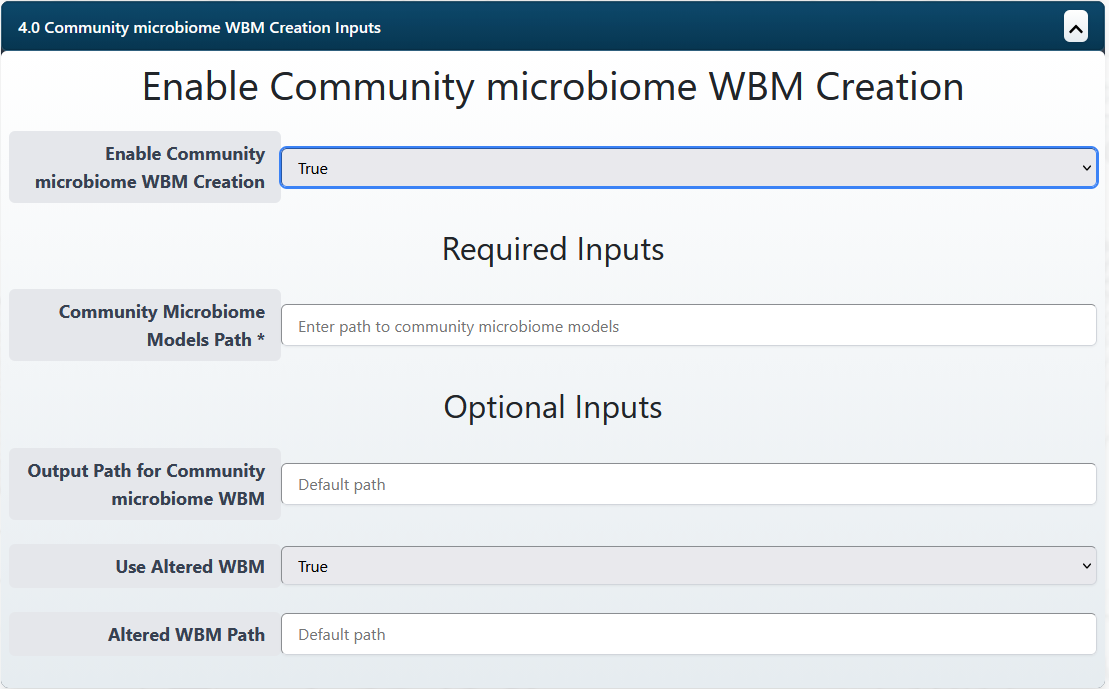

*Figure **7**. Various input parameters to create community microbiome WBMs. To see and fill in the input variables, set Enable Community microbiome WBM creation to true. If MgPipe is not set to true, a prompt is made to define the the path to the community microbiome models.*

Following a successful run, products of the pipeline will be located within the mWBMmodels folder. You will find the results:

- Community microbiome WBMs. They can be identified by their file name as they contain mWBM or miWBM and the sample ID.

- A file containing feasibility checks on the community microbiome WBMs. This can be used to find out which WBMs were infeasible and could or could not be fixed by updating the diet.

## Phase 4: Flux balance analysis and statistics inputs

### Flux Balance Analysis Inputs

Here we explain the input used in Persephone to perform flux balance analysis (FBA) and to analyse the results. First, we will explain the general variables used for FBA. Some input variables will be locked if community microbiome WBM creation is enabled to ensure proper data handling (Figure 8).

- To enable Persephone to perform FBA, you have to set the **Run Flux Balance Analysis (FBA)** (fbaFlag) variable to *True*. In the online configuration file creator, this will also allow you to fill in the rest of the input variables. When editing the configuration file in MATLAB, only use true or false as input, no apostrophes.

- The directory where the raw flux results are stored is defined in the variable **Output Path for Flux Results **(outputPathFluxResult). The variable is prefilled as Persephone is designed to have results in an easily accessible directory and it is not recommended to change this variable. If you want to edit this path in the configuration file in MATLAB, ensure that an apostrophe (‘) is at the start and end of the path to make sure MATLAB reads it as text.

Now that you have defined the general variables, we will explain the input variables that relate to setting up WBMs and optimising the reactions.

- You need to define which reactions you want to optimise in the **Reaction List **(rxnList) variable. The reactions can be either existing reactions in the WBMs or demand reactions in organs in biofluids. Please refer to the paper for in-depth information on how to structure and format the reaction names. When editing the configuration file in MATLAB, ensure that you start and end with curly brackets {}. Each entry needs to be separated with a comma and be between apostrophes to ensure MATLAB reads it as text. Alternatively, you can use readtable or readcell commands to load in a file you have prepared previously with all the reaction names. Extract the column with the reaction names so it is an nx1 cell array in the workspace. This option is for people who are more comfortable coding in MATLAB.

- To specify if reactions need to be maximised or minimised, enter either ‘min’ or ‘max’ in the **Reaction Sense**(rxnSense) variable. Alternatively, enter a comma-separated list with ‘min’ or ‘max’ for each entry you used for the **Reaction List **(rxnList) variable. Be aware that it is of no use to minimise user-created demand reactions. How to choose to minimise or maximise a reaction and how to interpret it can be found in the Persephone paper. When editing the configuration file in MATLAB, ensure that you start and end with curly brackets {}. Either use ‘min’ or ‘max’ if you want to minimise or maximise each reaction. Make sure you use the apostrophes: otherwise, MATLAB will not read the values as text. If you want to specify minimisation or maximisation for each reaction in the rxnList variable, separate each value in rxnSense with a comma. Alternatively, you can use the readtable or readcell commands to load in a file you have prepared previously with all the reaction names. Extract the column with the reaction sense so it is an nx1 cell array in the workspace. Ensure it is the same size as the rxnList variable. This option is for people who are more comfortable coding in MATLAB.

- If you want to save all information calculated and gathered during FBA, set the variable **Save Full Result **(saveFullRes) to *True*. We suggest doing this as it is good practice to keep most of the settings and results from the FBA. When editing the configuration file in MATLAB, only use true or false as input, no apostrophes.

- If you have community microbiome WBMs, you can choose to create and analyse germ-free WBMs. Germ-free WBM flux analyses can be used to get a different perspective on the actual microbial flux contribution by subtracting the germ-free flux from the community microbiome WBM flux. Set **Analyse germ free** (analyseGF) to true if you want germ-free WBMs to be created and analysed. For non-personalised WBMs, one random male and female community microbiome is made germ free and used to calculate germ-free fluxes. For community microbiome personalised WBMs, each WBM is made germ-free and used to compare with their original counterpart. Note that more personalised WBMs mean more FBAs are performed, which will increase total runtime.

The raw flux results are difficult to interpret, so Persephone performs processing to make the fluxes easier to interpret. The following input variables affect the way the fluxes are processed.

- The results from an optimisation may be a small number. At a certain point, it is difficult to say with accuracy if the flux value is actually that small or if it is because of numerical rounding. To account for that, we define a threshold in the **Numerical Rounding** (numericalRounding) variable. All the flux values beneath this threshold value are considered to be 0. It defaults to 1e-6, and we suggest only to change it when you have good reasons to. When editing the configuration file in MATLAB, use only numbers. No apostrophes are required.

- Some reactions you chose in the reaction List variable might not be influenced by the microbiome, or the samples might not show a difference in the flux value of that sample. In the variable **Reaction Removal Cutoff ** (rxnRemovalCutoff), you can set the method (a dropdown menu with fraction and count) to decide which reaction should be removed from further analysis. I.e., if you use fraction and set the cutoff to 0.1, at least 10% of the samples need to be unique. If you use count and set it to 5, there have to be at least 5 different flux values for a reaction across all samples. Depending on the size of your dataset, one method might work better than another. When editing the configuration file in MATLAB, start and end with a curly bracket {}. The first value should be either ‘fraction’ or ‘count’. Do not forget the apostrophe, as MATLAB will not treat it as text otherwise. Add a comma and then fill in the numeric value you want to use for reaction cutoff. 

- The place where the analysed flux results are stored is defined in the variable **Output Path for Flux Analysis** (outputPathFluxAnalysis). The variable is prefilled as Persephone is designed to have results in an easily accessible directory, and it is not recommended to change this variable. If you want to edit this path in the configuration file in MATLAB, ensure that an apostrophe (‘) is at the start and end of the path to make sure MATLAB reads it as text.

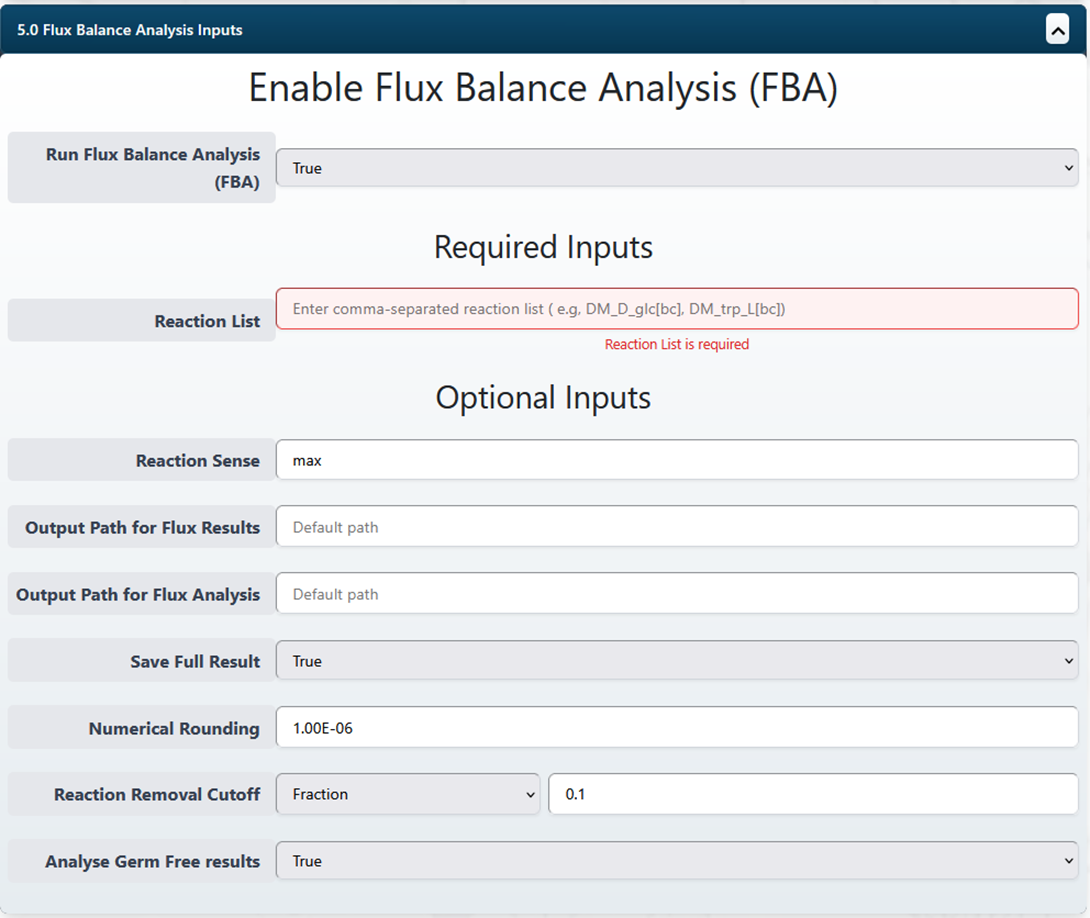

*Figure **8**. Various input parameters to run flux balance analysis. To see and fill in the input variables, set Run Flux Balance Analysis to true. The reaction list is the only required variable. If community microbiome creation and WBM personalisation are both false, a prompt is given to fill in the location of the WBMs to perform FBA on.*

Following a successful run, products of the pipeline will be located within the resultFlux folder. You will find the results:

- MATLAB structure files (.mat) that contain the results of the FBAs. They are recognised by their sample ID and fba_sol in the file name.

- A directory called fluxAnalysis, where the processed fluxes are stored in the flux_results Excel file. Three sheets from the flux_results file are saved as separate files for easy calling in the statistics part of Persephone. For an explanation of the flux_results file, please refer to the original Persephone Nature Protocol paper. 

### Statistical Analysis Inputs

In the last section of the SOP, we will go over the various inputs required to run the statistics in Persephone. Some inputs will be locked when flux balance analysis is enabled to ensure proper data handling (Figure 9).

- To enable Persephone to perform statistics, you have to set the **Run Statistical Analysis** (statisticsFlag) variable to True. In the online configuration file creator, this will also allow you to fill in the rest of the input variables. If you want to edit this path in the configuration file in MATLAB, ensure that an apostrophe (‘) is at the start and end of the path to make sure MATLAB reads it as text.

- Persephone needs to know which variables in your metadata are the ones driving your research question. In the input variable **Response Variables** (response), you can enter a comma-separated list of metadata variables that you want to serve as the response variable for the statistical analysis. Ensure the names used as inputs are the same names as the headers you want to use in the metadata. When editing the configuration file in MATLAB, ensure that you start and end with curly brackets {}. Each entry needs to be separated with a comma and be between apostrophes to ensure MATLAB reads it as text.

- The directory where statistical results and figures are stored is defined in the variable **Output Path for Statistical Analysis**(outputPathStat). The variable is prefilled as Persephone is designed to have results in an easily accessible directory, and it is not recommended to change this variable. If you want to edit this path in the configuration file in MATLAB, ensure that an apostrophe (‘) is at the start and end of the path to make sure MATLAB reads it as text.

- Control variables can be added to identify true relationships between predictor and response variables by accounting for biases and confounding factors in the data. Sex is always taken along as a confounding variable in Persephone, as WBMs have sex specific differences that will drive some of the flux results. Confounders can be defined in the variable **Confounders **(confounders). Enter as a comma-separated list. Be careful you don’t add too many, as that might cause overfitting of your data. You do not have to supply confounders. Ensure that each input value is a column header in your metadata. When editing the configuration file in MATLAB, ensure that you start and end with curly brackets {}. Each entry needs to be separated with a comma and be between apostrophes to ensure MATLAB reads it as text.

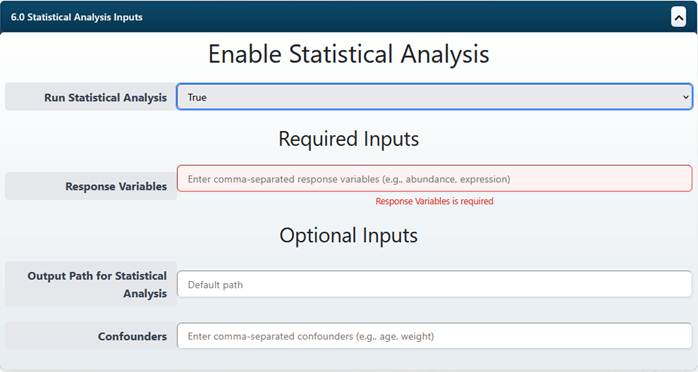

*Figure 9. Various input parameters to perform Statistics. To see and fill in the input variables, set Run Statistical Analysis to true. Only the response variable is a required input variable.*

Following a successful run, products of the pipeline will be located within the resultStatistics folder. You will find the following results:

- Directories for each value in the response variable

- In the directories for the response variables, an Excel file with the statistical results is stored, as well as heatmap and volcano plots of the various analyses performed. For an explanation of the files please, refer to the original Persephone Nature Protocol paper.

# How to: Download the configuration file and run Persephone

When you have filled in the sections you need, you can then download the .mat file by clicking the “Download Config File (.m)” button at the bottom of the page (Figure 10). It will not be able to download unless you have filled in all the required parameters. If you have missed required fields, a warning will pop up asking if you want to download the file anyway. Be aware that if you download the configuration file without filling all the required fields, errors could occur.

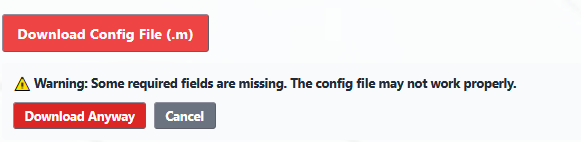

*Figure **10**. Download button with the warning that some required fields are missing. To download, click the download anyway button.*

Move your file from downloads into the directory you have for all your input data you made at the start of this SOP. When ready, open MATLAB and navigate in MATLAB to your input directory. It is good practice to open the configuration file in MATLAB and double-check your inputs are as you expect them. Once you are ready, enter in the command window of MATLAB (Figure 11)

            > runPersephone(‘configPersephone.m’)

If MATLAB is not in the directory with your input results, obtain the path to the directory where your configuration file is located and run

            > runPersephone(‘path to directory/configPersephone.m’)

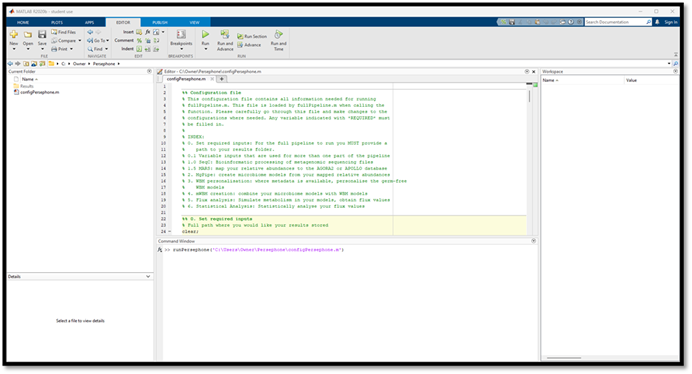

*Figure **11**. Example of how to run the runPersephone command within MATLAB.*

For troubleshooting and errors please see the original paper.

This concludes tutorial 1. Tutorials 2 through 5 show indepth information about the individual functions used in Persephone and additional information on working with WBMs and concepts important in metabolic modelling.